%Purpose:
    %Econ 525-Spring2019
%Note:
    %This m-file is dependent upon GDP.xlsx, 10_Industry_Portfolios.xlsx, MarketReturns.xlsx, and the MIDASv2.3 folder.
    %Find interpretations for 1e in Malik_Jabati_HW5_1e.docx.
%Author:
    %Malik Jabati — 28Feb2019
    %UNC Honor Pledge: I certify that no unauthorized assistance has been received or given in the completion of this work.
%Assumptions:
    %Used value-weighted returns for Fama-French 10 industry portfolios
    %Used value-weighted returns for S&P 500 market index returns


## Load in data


%HouseKeeping
    clear all; close all; clc
    
    addpath(genpath('MATLAB Drive/HW5/MIDASv2.3')); %Add MIDAS toolbox to path
    
    %I went through all the data in Excel, and it was clean. There were no NaNs, extreme values, or recurring zeros.
    [GDP_num,GDP_txt,GDP_raw] = xlsread('GDP.xlsx','Sheet1');
    
    [Portfolios_num,Portfolios_txt,Portfolios_raw] = xlsread('10_Industry_Portfolios.xlsx','Sheet1');
    
    [Index_num,Index_txt,Index_raw] = xlsread('MarketReturns.xlsx','Sheet1');
    Index_num(:,2) = Index_num(:,2)*100; %convert to percentage to standardize dataset
    
    %Convert dates to text
    GDP_dates = datetime(GDP_num(:,1),'ConvertFrom','datenum') + calyears(1900);
    GDP_dates = cellstr(datestr(GDP_dates,'mm/dd/yyyy'));
    
    Portfolios_dates = datetime(Portfolios_num(:,1),'ConvertFrom','datenum') + calyears(1900);
    Portfolios_dates = cellstr(datestr(Portfolios_dates, 'mm/dd/yyyy'));
    
    Index_dates = datetime(Index_num(:,1),'ConvertFrom','datenum') + calyears(1900);
    Index_dates = cellstr(datestr(Index_dates,'mm/dd/yyyy'));   
    
    %Standardize variable names
    GDP_Y = GDP_num(:,2);
    Portfolios_X = Portfolios_num(:,2:end);
    Index_X = Index_num(:,2);
    
    %Quick test to see if data is clean
    dirtyGDP = isnan(GDP_Y);
    dirtyPortfolios = isnan(Portfolios_X);
    dirtyIndex = isnan(Index_X);
    
    if(any(dirtyGDP,'all') == 1 || any(dirtyPortfolios,'all') == 1 || any(dirtyIndex,'all') == 1)   %check for any NaN values
        disp('WARNING: Missing values in data!')
    elseif(min(GDP_Y,[],'all')<=-50 || min(Portfolios_X,[],'all')<=-50 || min(Index_X,[],'all')<=-50) %check for any losses of 50+%
        disp('WARNING: Check data for unexpectedly small values!')
    elseif(max(GDP_Y,[],'all')>=50 || max(Portfolios_X,[],'all')>=50 || max(Index_X,[],'all')>=50) %check for any gains of 50+%
        disp('WARNING: Check data for unexpectedly large values!')
    else
        disp('Data appears to be clean.')
    end

Data appears to be clean.


    
    % Specify lag structure and sample size
    Xlag = 3;
    Ylag = 1;
    EstStart = '04/01/1947';
    EstEnd = '10/01/2016';
    Method = 'rollingwindow';
    

## 1.a Run the model for each portfolio and each horizon. Create a table that has industry names as rows, and horizons {3, 2, 1} as column headings, where table entries are the RMSE. See table below.

Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Sep-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(07/01/47),X(06/01/47),X(05/01/47)
Reg Y(01/01/48) on Y(10/01/47),X(10/01/47),X(09/01/47),X(08/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(07/02/16),X(06/02/16),X(05/02/16)


 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'     't-stat'
    'Const'            [    0.4780]    [NaN]    [   NaN]
    'HighFreqSlope'    [    0.0404]    [NaN]    [   NaN]
    'Beta1'            [   10.1564]    [NaN]    [   NaN]
    'Beta2'            [    4.8205]    [NaN]    [   NaN]
    'Ylag1'            [    0.3397]    [NaN]    [   NaN]

Goodness of fit:   0.15092
Noise variance:    0.78168
Log likelihood:    -355.8986
Akaike criteria:   -64.2947
Bayesian criteria: -46.1746
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Sep-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(07/01/47),X(06/01/47),X(05/01/47)
Reg Y(01/01/48) on Y(10/01/47),X(10/01/47),X(09/01/47),X(08/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(07/02/16),X(06/02/16),X(05/02/16)
 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'            't-stat'    
    'Const'            [    0.5117]    [    0.0678]    [    7.5510]
    'HighFreqSlope'    [    0.0370]    [    0.0106]    [    3.4864]
    'Beta1'            [    2.4532]    [2.1884e+05]    [1.1210e-05]
    'Beta2'            [    4.9715]    [4.4350e+05]    [1.1210e-05]
    'Ylag1'            [    0.3094]    [    0.0567]    [    5.4574]

Goodness of fit:   0.16594
Noise variance:    0.76786
Log likelihood:    -353.4278
Akaike criteria:   -69.2364
Bayesian criteria: -51.1163
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Sep-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(07/01/47),X(06/01/47),X(05/01/47)
Reg Y(01/01/48) on Y(10/01/47),X(10/01/47),X(09/01/47),X(08/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(07/02/16),X(06/02/16),X(05/02/16)


 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'     't-stat'
    'Const'            [    0.4996]    [NaN]    [   NaN]
    'HighFreqSlope'    [    0.0435]    [NaN]    [   NaN]
    'Beta1'            [    3.3688]    [NaN]    [   NaN]
    'Beta2'            [    4.9536]    [NaN]    [   NaN]
    'Ylag1'            [    0.3199]    [NaN]    [   NaN]

Goodness of fit:   0.16491
Noise variance:    0.7688
Log likelihood:    -353.5987
Akaike criteria:   -68.8946
Bayesian criteria: -50.7745
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Sep-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(07/01/47),X(06/01/47),X(05/01/47)
Reg Y(01/01/48) on Y(10/01/47),X(10/01/47),X(09/01/47),X(08/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(07/02/16),X(06/02/16),X(05/02/16)


 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'     't-stat'
    'Const'            [    0.4926]    [NaN]    [   NaN]
    'HighFreqSlope'    [    0.0252]    [NaN]    [   NaN]
    'Beta1'            [    9.3890]    [NaN]    [   NaN]
    'Beta2'            [    4.8355]    [NaN]    [   NaN]
    'Ylag1'            [    0.3342]    [NaN]    [   NaN]

Goodness of fit:   0.14587
Noise variance:    0.78633
Log likelihood:    -356.7206
Akaike criteria:   -62.6508
Bayesian criteria: -44.5307
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Sep-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(07/01/47),X(06/01/47),X(05/01/47)
Reg Y(01/01/48) on Y(10/01/47),X(10/01/47),X(09/01/47),X(08/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(07/02/16),X(06/02/16),X(05/02/16)


 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'     't-stat'
    'Const'            [    0.4983]    [NaN]    [   NaN]
    'HighFreqSlope'    [    0.0406]    [NaN]    [   NaN]
    'Beta1'            [    2.8840]    [NaN]    [   NaN]
    'Beta2'            [    4.9631]    [NaN]    [   NaN]
    'Ylag1'            [    0.3249]    [NaN]    [   NaN]

Goodness of fit:   0.18503
Noise variance:    0.75028
Log likelihood:    -350.2208
Akaike criteria:   -75.6504
Bayesian criteria: -57.5304
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Sep-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(07/01/47),X(06/01/47),X(05/01/47)
Reg Y(01/01/48) on Y(10/01/47),X(10/01/47),X(09/01/47),X(08/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(07/02/16),X(06/02/16),X(05/02/16)
 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'            't-stat'    
    'Const'            [    0.4812]    [    0.0688]    [    6.9973]
    'HighFreqSlope'    [    0.0334]    [    0.0132]    [    2.5366]
    'Beta1'            [    2.6053]    [3.3199e+05]    [7.8474e-06]
    'Beta2'            [    4.9685]    [6.3314e+05]    [7.8474e-06]
    'Ylag1'            [    0.3415]    [    0.0559]    [    6.1124]

Goodness of fit:   0.14904
Noise variance:    0.78341
Log likelihood:    -356.205
Akaike criteria:   -63.6819
Bayesian criteria: -45.5618
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Sep-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(07/01/47),X(06/01/47),X(05/01/47)
Reg Y(01/01/48) on Y(10/01/47),X(10/01/47),X(09/01/47),X(08/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(07/02/16),X(06/02/16),X(05/02/16)
 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'            't-stat'    
    'Const'            [    0.4888]    [    0.0685]    [    7.1321]
    'HighFreqSlope'    [    0.0316]    [    0.0126]    [    2.5027]
    'Beta1'            [    2.7757]    [4.0856e+05]    [6.7940e-06]
    'Beta2'            [    4.9652]    [7.3082e+05]    [6.7940e-06]
    'Ylag1'            [    0.3373]    [    0.0561]    [    6.0082]

Goodness of fit:   0.14853
Noise variance:    0.78388
Log likelihood:    -356.2888
Akaike criteria:   -63.5142
Bayesian criteria: -45.3942
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Sep-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(07/01/47),X(06/01/47),X(05/01/47)
Reg Y(01/01/48) on Y(10/01/47),X(10/01/47),X(09/01/47),X(08/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(07/02/16),X(06/02/16),X(05/02/16)
 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'        't-stat' 
    'Const'            [    0.4771]    [0.0696]    [ 6.8539]
    'HighFreqSlope'    [    0.0329]    [0.0159]    [ 2.0667]
    'Beta1'            [  102.4290]    [2.8747]    [35.6312]
    'Beta2'            [    3.0115]    [0.0557]    [54.0447]
    'Ylag1'            [    0.3417]    [0.0563]    [ 6.0729]

Goodness of fit:   0.14308
Noise variance:    0.7889
Log likelihood:    -357.1723
Akaike criteria:   -61.7474
Bayesian criteria: -43.6273
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Sep-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(07/01/47),X(06/01/47),X(05/01/47)
Reg Y(01/01/48) on Y(10/01/47),X(10/01/47),X(09/01/47),X(08/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(07/02/16),X(06/02/16),X(05/02/16)


 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'     't-stat'
    'Const'            [    0.4864]    [NaN]    [   NaN]
    'HighFreqSlope'    [    0.0271]    [NaN]    [   NaN]
    'Beta1'            [    2.5166]    [NaN]    [   NaN]
    'Beta2'            [    4.9703]    [NaN]    [   NaN]
    'Ylag1'            [    0.3434]    [NaN]    [   NaN]

Goodness of fit:   0.13924
Noise variance:    0.79243
Log likelihood:    -357.7917
Akaike criteria:   -60.5086
Bayesian criteria: -42.3885
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Sep-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(07/01/47),X(06/01/47),X(05/01/47)
Reg Y(01/01/48) on Y(10/01/47),X(10/01/47),X(09/01/47),X(08/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(07/02/16),X(06/02/16),X(05/02/16)


 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'        't-stat'
    'Const'            [    0.4960]    [0.0678]    [7.3188]
    'HighFreqSlope'    [    0.0407]    [0.0120]    [3.3828]
    'Beta1'            [    3.0262]    [   NaN]    [   NaN]
    'Beta2'            [    4.9603]    [   NaN]    [   NaN]
    'Ylag1'            [    0.3213]    [0.0561]    [5.7299]

Goodness of fit:   0.16387
Noise variance:    0.76976
Log likelihood:    -353.7704
Akaike criteria:   -68.5511
Bayesian criteria: -50.431
 


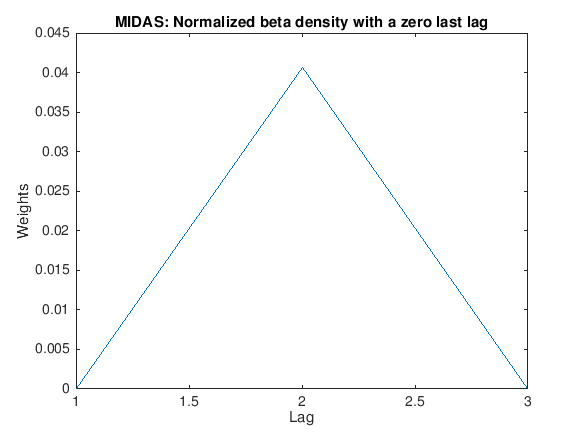


    %For a horizon of 3   
    Horizon = 3;
    
    Portfolios_forecasts3 = cell(10,1);
    
    for i=1:10 %10 industry portfolios
        Portfolios_forecasts3{i} = MIDAS_ADL(GDP_Y,GDP_dates,Portfolios_X(:,i),Portfolios_dates,'Xlag',Xlag,'Ylag',Ylag,...
            'Horizon',Horizon,'EstStart',EstStart,'EstEnd',EstEnd,'Polynomial','beta','Method',Method);
    end

Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Aug-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(08/01/47),X(07/01/47),X(06/01/47)
Reg Y(01/01/48) on Y(10/01/47),X(11/01/47),X(10/01/47),X(09/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(08/02/16),X(07/02/16),X(06/02/16)


 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'     't-stat'
    'Const'            [    0.4648]    [NaN]    [   NaN]
    'HighFreqSlope'    [    0.0331]    [NaN]    [   NaN]
    'Beta1'            [1.0000e-08]    [NaN]    [   NaN]
    'Beta2'            [    5.0196]    [NaN]    [   NaN]
    'Ylag1'            [    0.3529]    [NaN]    [   NaN]

Goodness of fit:   0.14801
Noise variance:    0.78436
Log likelihood:    -356.3732
Akaike criteria:   -63.3456
Bayesian criteria: -45.2255
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Aug-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(08/01/47),X(07/01/47),X(06/01/47)
Reg Y(01/01/48) on Y(10/01/47),X(11/01/47),X(10/01/47),X(09/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(08/02/16),X(07/02/16),X(06/02/16)
 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'        't-stat' 
    'Const'            [    0.4809]    [0.0687]    [ 6.9954]
    'HighFreqSlope'    [    0.0345]    [0.0117]    [ 2.9408]
    'Beta1'            [    1.0613]    [0.0911]    [11.6480]
    'Beta2'            [    4.9988]    [4.6489]    [ 1.0753]
    'Ylag1'            [    0.3397]    [0.0556]    [ 6.1076]

Goodness of fit:   0.15583
Noise variance:    0.77716
Log likelihood:    -355.0962
Akaike criteria:   -65.8995
Bayesian criteria: -47.7794
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Aug-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(08/01/47),X(07/01/47),X(06/01/47)
Reg Y(01/01/48) on Y(10/01/47),X(11/01/47),X(10/01/47),X(09/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(08/02/16),X(07/02/16),X(06/02/16)


 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'        't-stat'
    'Const'            [    0.4748]    [0.0691]    [6.8748]
    'HighFreqSlope'    [    0.0345]    [0.0142]    [2.4256]
    'Beta1'            [    1.0218]    [   NaN]    [   NaN]
    'Beta2'            [    4.9996]    [   NaN]    [   NaN]
    'Ylag1'            [    0.3383]    [0.0560]    [6.0419]

Goodness of fit:   0.15157
Noise variance:    0.78108
Log likelihood:    -355.7933
Akaike criteria:   -64.5054
Bayesian criteria: -46.3853
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Aug-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(08/01/47),X(07/01/47),X(06/01/47)
Reg Y(01/01/48) on Y(10/01/47),X(11/01/47),X(10/01/47),X(09/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(08/02/16),X(07/02/16),X(06/02/16)


 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'        't-stat'
    'Const'            [    0.4960]    [0.0693]    [7.1612]
    'HighFreqSlope'    [    0.0083]    [0.0103]    [0.7988]
    'Beta1'            [    0.6855]    [   NaN]    [   NaN]
    'Beta2'            [    5.0062]    [   NaN]    [   NaN]
    'Ylag1'            [    0.3549]    [0.0562]    [6.3096]

Goodness of fit:   0.13121
Noise variance:    0.79982
Log likelihood:    -359.077
Akaike criteria:   -57.9379
Bayesian criteria: -39.8179
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Aug-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(08/01/47),X(07/01/47),X(06/01/47)
Reg Y(01/01/48) on Y(10/01/47),X(11/01/47),X(10/01/47),X(09/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(08/02/16),X(07/02/16),X(06/02/16)


 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'        't-stat'
    'Const'            [    0.4720]    [0.0692]    [6.8167]
    'HighFreqSlope'    [    0.0273]    [0.0108]    [2.5185]
    'Beta1'            [    1.0458]    [   NaN]    [   NaN]
    'Beta2'            [    4.9991]    [   NaN]    [   NaN]
    'Ylag1'            [    0.3471]    [0.0556]    [6.2477]

Goodness of fit:   0.15088
Noise variance:    0.78172
Log likelihood:    -355.9053
Akaike criteria:   -64.2812
Bayesian criteria: -46.1612
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Aug-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(08/01/47),X(07/01/47),X(06/01/47)
Reg Y(01/01/48) on Y(10/01/47),X(11/01/47),X(10/01/47),X(09/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(08/02/16),X(07/02/16),X(06/02/16)


 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'        't-stat'
    'Const'            [    0.4764]    [0.0699]    [6.8182]
    'HighFreqSlope'    [    0.0297]    [0.0160]    [1.8559]
    'Beta1'            [    1.0441]    [   NaN]    [   NaN]
    'Beta2'            [    4.9991]    [   NaN]    [   NaN]
    'Ylag1'            [    0.3587]    [0.0558]    [6.4258]

Goodness of fit:   0.14061
Noise variance:    0.79118
Log likelihood:    -357.5714
Akaike criteria:   -60.9492
Bayesian criteria: -42.8291
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Aug-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(08/01/47),X(07/01/47),X(06/01/47)
Reg Y(01/01/48) on Y(10/01/47),X(11/01/47),X(10/01/47),X(09/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(08/02/16),X(07/02/16),X(06/02/16)


 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'        't-stat'
    'Const'            [    0.4599]    [0.0699]    [6.5803]
    'HighFreqSlope'    [    0.0339]    [0.0136]    [2.4885]
    'Beta1'            [    1.0095]    [   NaN]    [   NaN]
    'Beta2'            [    4.9998]    [   NaN]    [   NaN]
    'Ylag1'            [    0.3512]    [0.0554]    [6.3367]

Goodness of fit:   0.15286
Noise variance:    0.7799
Log likelihood:    -355.5825
Akaike criteria:   -64.9269
Bayesian criteria: -46.8069
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Aug-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(08/01/47),X(07/01/47),X(06/01/47)
Reg Y(01/01/48) on Y(10/01/47),X(11/01/47),X(10/01/47),X(09/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(08/02/16),X(07/02/16),X(06/02/16)


 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'     't-stat'
    'Const'            [    0.4703]    [NaN]    [   NaN]
    'HighFreqSlope'    [    0.0224]    [NaN]    [   NaN]
    'Beta1'            [1.0000e-08]    [NaN]    [   NaN]
    'Beta2'            [    5.0197]    [NaN]    [   NaN]
    'Ylag1'            [    0.3598]    [NaN]    [   NaN]

Goodness of fit:   0.14157
Noise variance:    0.79029
Log likelihood:    -357.417
Akaike criteria:   -61.258
Bayesian criteria: -43.1379
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Aug-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(08/01/47),X(07/01/47),X(06/01/47)
Reg Y(01/01/48) on Y(10/01/47),X(11/01/47),X(10/01/47),X(09/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(08/02/16),X(07/02/16),X(06/02/16)


 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'        't-stat'
    'Const'            [    0.4592]    [0.0709]    [6.4740]
    'HighFreqSlope'    [    0.0461]    [0.0186]    [2.4729]
    'Beta1'            [    1.0300]    [   NaN]    [   NaN]
    'Beta2'            [    4.9994]    [   NaN]    [   NaN]
    'Ylag1'            [    0.3630]    [0.0554]    [6.5532]

Goodness of fit:   0.1534
Noise variance:    0.77939
Log likelihood:    -355.4935
Akaike criteria:   -65.105
Bayesian criteria: -46.9849
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Aug-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(08/01/47),X(07/01/47),X(06/01/47)
Reg Y(01/01/48) on Y(10/01/47),X(11/01/47),X(10/01/47),X(09/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(08/02/16),X(07/02/16),X(06/02/16)


 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'        't-stat'
    'Const'            [    0.4814]    [0.0688]    [6.9927]
    'HighFreqSlope'    [    0.0306]    [0.0129]    [2.3730]
    'Beta1'            [    1.0202]    [   NaN]    [   NaN]
    'Beta2'            [    4.9996]    [   NaN]    [   NaN]
    'Ylag1'            [    0.3435]    [0.0557]    [6.1635]

Goodness of fit:   0.15114
Noise variance:    0.78148
Log likelihood:    -355.863
Akaike criteria:   -64.3659
Bayesian criteria: -46.2458
 


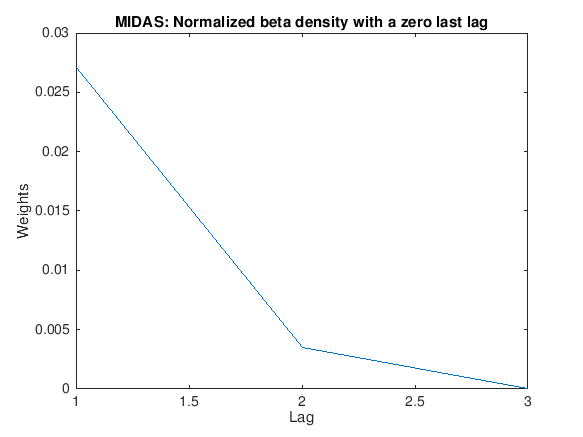

    
    Portfolios_RMSE3 = zeros([10 1]);
    
    for i=1:10 %10 industry portfolios
        Portfolios_RMSE3(i) = Portfolios_forecasts3{i,1}.RMSE;
    end
    
    %For a horizon of 2   
    Horizon = 2;
    
    Portfolios_forecasts2 = cell(10,1);
    
    for i=1:10 %10 industry portfolios
        Portfolios_forecasts2{i} = MIDAS_ADL(GDP_Y,GDP_dates,Portfolios_X(:,i),Portfolios_dates,'Xlag',Xlag,'Ylag',Ylag,...
            'Horizon',Horizon,'EstStart',EstStart,'EstEnd',EstEnd,'Polynomial','beta','Method',Method);
    end

Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Jul-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(07/01/47) on Y(04/01/47),X(06/01/47),X(05/01/47),X(04/01/47)
Reg Y(10/01/47) on Y(07/01/47),X(09/01/47),X(08/01/47),X(07/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(09/02/16),X(08/02/16),X(07/02/16)
 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'        't-stat' 
    'Const'            [    0.4368]    [0.0705]    [ 6.1996]
    'HighFreqSlope'    [    0.0612]    [0.0185]    [ 3.3081]
    'Beta1'            [    1.0709]    [0.0704]    [15.2086]
    'Beta2'            [    4.9986]    [3.5881]    [ 1.3931]
    'Ylag1'            [    0.3619]    [0.0550]    [ 6.5789]

Goodness of fit:   0.16343
Noise variance:    0.76965
Log likelihood:    -355.0388
Akaike criteria:   -68.8523
Bayesian criteria: -50.7142
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Jul-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(07/01/47) on Y(04/01/47),X(06/01/47),X(05/01/47),X(04/01/47)
Reg Y(10/01/47) on Y(07/01/47),X(09/01/47),X(08/01/47),X(07/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(09/02/16),X(08/02/16),X(07/02/16)
 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'        't-stat' 
    'Const'            [    0.4820]    [0.0668]    [ 7.2163]
    'HighFreqSlope'    [    0.0568]    [0.0129]    [ 4.3892]
    'Beta1'            [    1.0563]    [0.0899]    [11.7477]
    'Beta2'            [    4.9989]    [4.6074]    [ 1.0850]
    'Ylag1'            [    0.3352]    [0.0543]    [ 6.1688]

Goodness of fit:   0.19014
Noise variance:    0.74507
Log likelihood:    -350.5279
Akaike criteria:   -77.8741
Bayesian criteria: -59.736
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Jul-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(07/01/47) on Y(04/01/47),X(06/01/47),X(05/01/47),X(04/01/47)
Reg Y(10/01/47) on Y(07/01/47),X(09/01/47),X(08/01/47),X(07/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(09/02/16),X(08/02/16),X(07/02/16)
 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'        't-stat' 
    'Const'            [    0.4607]    [0.0678]    [ 6.7954]
    'HighFreqSlope'    [    0.0667]    [0.0162]    [ 4.1134]
    'Beta1'            [    1.0683]    [0.0542]    [19.7020]
    'Beta2'            [    4.9987]    [2.7665]    [ 1.8068]
    'Ylag1'            [    0.3349]    [0.0548]    [ 6.1126]

Goodness of fit:   0.18079
Noise variance:    0.75367
Log likelihood:    -352.1232
Akaike criteria:   -74.6833
Bayesian criteria: -56.5452
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Jul-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(07/01/47) on Y(04/01/47),X(06/01/47),X(05/01/47),X(04/01/47)
Reg Y(10/01/47) on Y(07/01/47),X(09/01/47),X(08/01/47),X(07/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(09/02/16),X(08/02/16),X(07/02/16)


 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'        't-stat'
    'Const'            [    0.4606]    [0.0686]    [6.7165]
    'HighFreqSlope'    [    0.0475]    [0.0148]    [3.2095]
    'Beta1'            [    1.0466]    [   NaN]    [   NaN]
    'Beta2'            [    4.9991]    [   NaN]    [   NaN]
    'Ylag1'            [    0.3507]    [0.0550]    [6.3743]

Goodness of fit:   0.16663
Noise variance:    0.7667
Log likelihood:    -354.5054
Akaike criteria:   -69.9191
Bayesian criteria: -51.781
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Jul-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(07/01/47) on Y(04/01/47),X(06/01/47),X(05/01/47),X(04/01/47)
Reg Y(10/01/47) on Y(07/01/47),X(09/01/47),X(08/01/47),X(07/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(09/02/16),X(08/02/16),X(07/02/16)


 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'     't-stat'
    'Const'            [    0.4799]    [NaN]    [   NaN]
    'HighFreqSlope'    [    0.0212]    [NaN]    [   NaN]
    'Beta1'            [    2.0085]    [NaN]    [   NaN]
    'Beta2'            [    4.9802]    [NaN]    [   NaN]
    'Ylag1'            [    0.3508]    [NaN]    [   NaN]

Goodness of fit:   0.1493
Noise variance:    0.78264
Log likelihood:    -357.3664
Akaike criteria:   -64.1971
Bayesian criteria: -46.059
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Jul-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(07/01/47) on Y(04/01/47),X(06/01/47),X(05/01/47),X(04/01/47)
Reg Y(10/01/47) on Y(07/01/47),X(09/01/47),X(08/01/47),X(07/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(09/02/16),X(08/02/16),X(07/02/16)
 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'        't-stat' 
    'Const'            [    0.4569]    [0.0699]    [ 6.5339]
    'HighFreqSlope'    [    0.0516]    [0.0186]    [ 2.7806]
    'Beta1'            [    1.0745]    [0.0681]    [15.7759]
    'Beta2'            [    4.9985]    [3.4722]    [ 1.4396]
    'Ylag1'            [    0.3603]    [0.0552]    [ 6.5241]

Goodness of fit:   0.1541
Noise variance:    0.77823
Log likelihood:    -356.5805
Akaike criteria:   -65.7689
Bayesian criteria: -47.6308
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Jul-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(07/01/47) on Y(04/01/47),X(06/01/47),X(05/01/47),X(04/01/47)
Reg Y(10/01/47) on Y(07/01/47),X(09/01/47),X(08/01/47),X(07/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(09/02/16),X(08/02/16),X(07/02/16)
 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'        't-stat' 
    'Const'            [    0.4411]    [0.0694]    [ 6.3544]
    'HighFreqSlope'    [    0.0579]    [0.0157]    [ 3.6833]
    'Beta1'            [    1.0751]    [0.0588]    [18.2875]
    'Beta2'            [    4.9985]    [2.9957]    [ 1.6686]
    'Ylag1'            [    0.3540]    [0.0547]    [ 6.4693]

Goodness of fit:   0.17098
Noise variance:    0.7627
Log likelihood:    -353.7777
Akaike criteria:   -71.3743
Bayesian criteria: -53.2362
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Jul-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(07/01/47) on Y(04/01/47),X(06/01/47),X(05/01/47),X(04/01/47)
Reg Y(10/01/47) on Y(07/01/47),X(09/01/47),X(08/01/47),X(07/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(09/02/16),X(08/02/16),X(07/02/16)
 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'        't-stat' 
    'Const'            [    0.4549]    [0.0706]    [ 6.4480]
    'HighFreqSlope'    [    0.0411]    [0.0159]    [ 2.5809]
    'Beta1'            [    1.0790]    [0.0767]    [14.0652]
    'Beta2'            [    4.9985]    [3.9094]    [ 1.2786]
    'Ylag1'            [    0.3581]    [0.0554]    [ 6.4688]

Goodness of fit:   0.1509
Noise variance:    0.78117
Log likelihood:    -357.1049
Akaike criteria:   -64.72
Bayesian criteria: -46.5819
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Jul-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(07/01/47) on Y(04/01/47),X(06/01/47),X(05/01/47),X(04/01/47)
Reg Y(10/01/47) on Y(07/01/47),X(09/01/47),X(08/01/47),X(07/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(09/02/16),X(08/02/16),X(07/02/16)
 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'        't-stat' 
    'Const'            [    0.4299]    [0.0697]    [ 6.1642]
    'HighFreqSlope'    [    0.0730]    [0.0188]    [ 3.8797]
    'Beta1'            [    1.0717]    [0.0595]    [18.0098]
    'Beta2'            [    4.9986]    [3.0340]    [ 1.6475]
    'Ylag1'            [    0.3709]    [0.0546]    [ 6.7950]

Goodness of fit:   0.17533
Noise variance:    0.7587
Log likelihood:    -353.0465
Akaike criteria:   -72.8368
Bayesian criteria: -54.6987
 


Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 01-Jul-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(07/01/47) on Y(04/01/47),X(06/01/47),X(05/01/47),X(04/01/47)
Reg Y(10/01/47) on Y(07/01/47),X(09/01/47),X(08/01/47),X(07/01/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(09/02/16),X(08/02/16),X(07/02/16)
 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'        't-stat' 
    'Const'            [    0.4599]    [0.0678]    [ 6.7844]
    'HighFreqSlope'    [    0.0604]    [0.0147]    [ 4.1025]
    'Beta1'            [    1.0651]    [0.0622]    [17.1337]
    'Beta2'            [    4.9987]    [3.1725]    [ 1.5756]
    'Ylag1'            [    0.3446]    [0.0546]    [ 6.3141]

Goodness of fit:   0.18056
Noise variance:    0.75389
Log likelihood:    -352.1629
Akaike criteria:   -74.6041
Bayesian criteria: -56.466
 


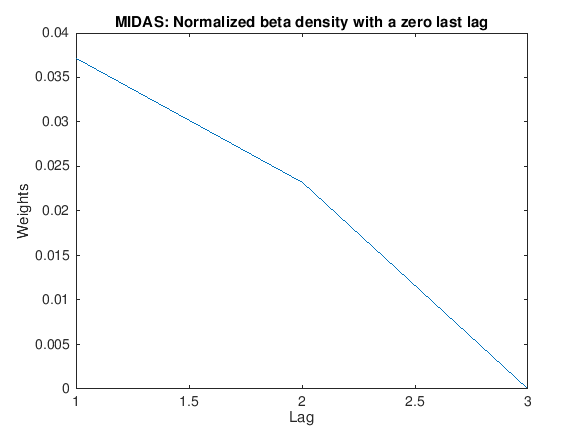

    
    Portfolios_RMSE2 = zeros([10 1]);
    
    for i=1:10 %10 industry portfolios
        Portfolios_RMSE2(i) = Portfolios_forecasts2{i,1}.RMSE;
    end
 
    %For a horizon of 1   
    Horizon = 1;
    
    Portfolios_forecasts1 = cell(10,1);
    
    for i=1:10 %10 industry portfolios
        Portfolios_forecasts1{i} = MIDAS_ADL(GDP_Y,GDP_dates,Portfolios_X(:,i),Portfolios_dates,'Xlag',Xlag,'Ylag',Ylag,...
            'Horizon',Horizon,'EstStart',EstStart,'EstEnd',EstEnd,'Polynomial','beta','Method',Method);
    end

    
    Portfolios_RMSE1 = zeros([10 1]);
    
    for i=1:10 %10 industry portfolios
        Portfolios_RMSE1(i) = Portfolios_forecasts1{i,1}.RMSE;
    end
    
    RmseForecastResults = array2table([Portfolios_RMSE3 Portfolios_RMSE2 Portfolios_RMSE1],...
        'RowNames',Portfolios_txt(1,2:end),'VariableNames',{'Hor_3','Hor_2', 'Hor_1'})

RmseForecastResults = 10×3 table
              Hor_3       Hor_2       Hor_1  
             ________    ________    ________

    NoDur    0.078918    0.086539    0.099371
    Durbl     0.16695     0.17645      0.3101
    Manuf     0.14981     0.20007     0.23719
    Enrgy     0.16109     0.16924     0.31202
    HiTec     0.17209     0.16803     0.16597
    Telcm     0.12191     0.18028     0.23973
    Shops     0.12028     0.16207     0.15451
    Hlth      0.18719     0.15145     0.16414
    Utils     0.13884     0.14975     0.12061
    Other     0.17931      0.2607     0.32253


## 1.b  Construct a forecast combination of the results above (using the default combination scheme).


    %Horizon of 3
    Combo3 = ForecastCombine(Portfolios_forecasts3{1},Portfolios_forecasts3{2},Portfolios_forecasts3{3},Portfolios_forecasts3{4},...
        Portfolios_forecasts3{5},Portfolios_forecasts3{6},Portfolios_forecasts3{7},Portfolios_forecasts3{8},...
        Portfolios_forecasts3{9},Portfolios_forecasts3{10});
    
    Combo_RMSE3 = sqrt(mean((Combo3-GDP_Y(280:end)).^2));
    
    %Horizon of 2
    Combo2 = ForecastCombine(Portfolios_forecasts2{1},Portfolios_forecasts2{2},Portfolios_forecasts2{3},Portfolios_forecasts2{4},...
        Portfolios_forecasts2{5},Portfolios_forecasts2{6},Portfolios_forecasts2{7},Portfolios_forecasts2{8},...
        Portfolios_forecasts2{9},Portfolios_forecasts2{10});
    
    Combo_RMSE2 = sqrt(mean((Combo2-GDP_Y(280:end)).^2));
    
    %Horizon of 1
    Combo1 = ForecastCombine(Portfolios_forecasts1{1},Portfolios_forecasts1{2},Portfolios_forecasts1{3},Portfolios_forecasts1{4},...
        Portfolios_forecasts1{5},Portfolios_forecasts1{6},Portfolios_forecasts1{7},Portfolios_forecasts1{8},...
        Portfolios_forecasts1{9},Portfolios_forecasts1{10});
    
    Combo_RMSE1 = sqrt(mean((Combo1-GDP_Y(280:end)).^2));
    

## 1.c Now run the same model from part a with market index returns instead of industry returns.

Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 30-Sep-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(07/31/47),X(06/30/47),X(05/29/47)
Reg Y(01/01/48) on Y(10/01/47),X(10/31/47),X(09/30/47),X(08/29/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(07/30/16),X(07/01/16),X(06/01/16)
 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'            't-stat'    
    'Const'            [    0.4914]    [    0.0675]    [    7.2836]
    'HighFreqSlope'    [    0.0545]    [    0.0144]    [    3.7771]
    'Beta1'            [    3.2400]    [3.0787e+05]    [1.0524e-05]
    'Beta2'            [    4.9561]    [4.7093e+05]    [1.0524e-05]
    'Ylag1'            [    0.3127]    [    0.0560]    [    5.5786]

Goodness of fit:   0.172
Noise variance:    0.76227
Log likelihood:    -352.4168
Akaike criteria:   -71.2584
Bayesian criteria: -53.1383
 


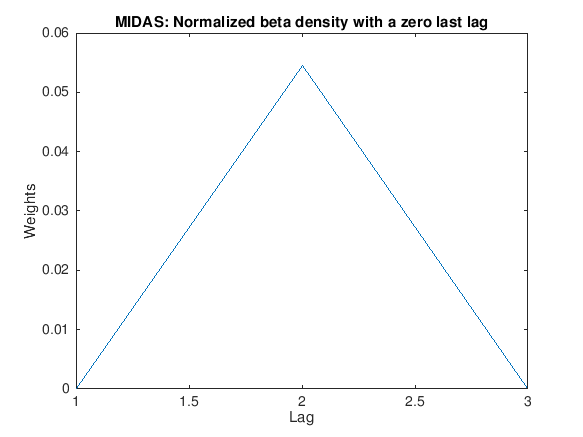

    %For a horizon of 3   
    Horizon = 3;
    
    Index_forecast3 = MIDAS_ADL(GDP_Y,GDP_dates,Index_X,Index_dates,'Xlag',Xlag,'Ylag',Ylag,...
        'Horizon',Horizon,'EstStart',EstStart,'EstEnd',EstEnd,'Polynomial','beta','Method',Method);

Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 29-Aug-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(08/29/47),X(07/31/47),X(06/30/47)
Reg Y(01/01/48) on Y(10/01/47),X(11/29/47),X(10/31/47),X(09/30/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(09/01/16),X(07/30/16),X(07/01/16)


 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'        't-stat'
    'Const'            [    0.4741]    [0.0695]    [6.8233]
    'HighFreqSlope'    [    0.0382]    [0.0162]    [2.3556]
    'Beta1'            [    1.0307]    [   NaN]    [   NaN]
    'Beta2'            [    4.9994]    [   NaN]    [   NaN]
    'Ylag1'            [    0.3447]    [0.0557]    [6.1833]

Goodness of fit:   0.15033
Noise variance:    0.78222
Log likelihood:    -355.9953
Akaike criteria:   -64.1014
Bayesian criteria: -45.9813
 


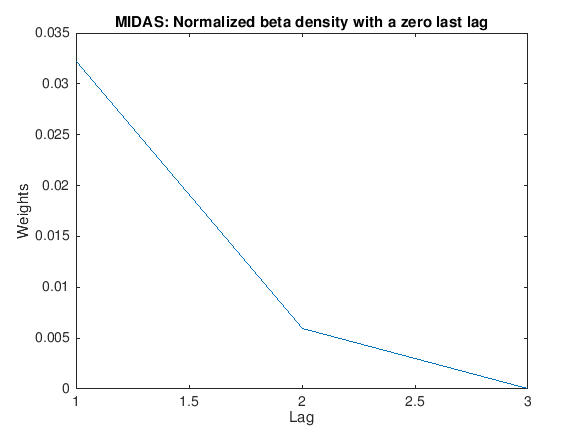

    
    Index_RMSE3 = Index_forecast3.RMSE;
    
    %For a horizon of 2   
    Horizon = 2;
    
    Index_forecast2 = MIDAS_ADL(GDP_Y,GDP_dates,Index_X,Index_dates,'Xlag',Xlag,'Ylag',Ylag,...
        'Horizon',Horizon,'EstStart',EstStart,'EstEnd',EstEnd,'Polynomial','beta','Method',Method);

Frequency of Data Y: 3 month(s)
Frequency of Data X: 1 month(s)
Start    Date: 31-Jul-1947
Terminal Date: 01-Oct-2016

Mixed frequency regression time frame:
Reg Y(10/01/47) on Y(07/01/47),X(09/30/47),X(08/29/47),X(07/31/47)
Reg Y(01/01/48) on Y(10/01/47),X(12/31/47),X(11/29/47),X(10/31/47)
...
Reg Y(10/02/16) on Y(07/02/16),X(10/01/16),X(09/01/16),X(07/30/16)
 
MIDAS: Normalized beta density with a zero last lag
    ''                 ' Estimator'    'SE'        't-stat' 
    'Const'            [    0.4501]    [0.0679]    [ 6.6286]
    'HighFreqSlope'    [    0.0807]    [0.0187]    [ 4.3235]
    'Beta1'            [    1.0663]    [0.0518]    [20.5671]
    'Beta2'            [    4.9987]    [2.6460]    [ 1.8892]
    'Ylag1'            [    0.3355]    [0.0546]    [ 6.1493]

Goodness of fit:   0.18496
Noise variance:    0.75034
Log likelihood:    -350.2324
Akaike criteria:   -75.6271
Bayesian criteria: -57.507
 


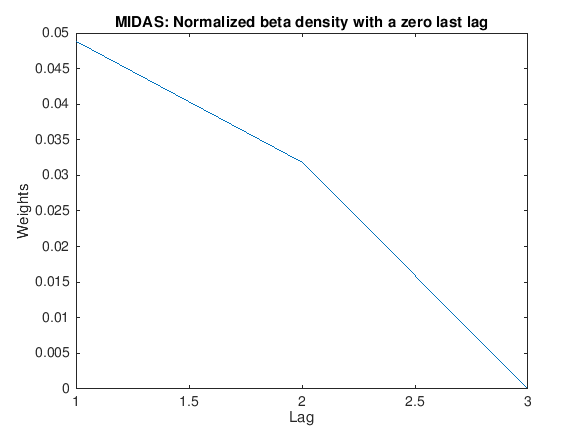

    
    Index_RMSE2 = Index_forecast2.RMSE;
    
    %For a horizon of 1   
    Horizon = 1;
    
    Index_forecast1 = MIDAS_ADL(GDP_Y,GDP_dates,Index_X,Index_dates,'Xlag',Xlag,'Ylag',Ylag,...
        'Horizon',Horizon,'EstStart',EstStart,'EstEnd',EstEnd,'Polynomial','beta','Method',Method);

    
    Index_RMSE1 = Index_forecast1.RMSE;
    

## 1.d Append two rows to the bottom of the table created in part a. Input the MSE of the default combination scheme and the MSE from the results in part c.

    
    ComboRMSEs = array2table([Combo_RMSE3 Combo_RMSE2 Combo_RMSE1],...
        'RowNames',{'combo default'},'VariableNames',{'Hor_3','Hor_2', 'Hor_1'});
    
    IndexRMSEs = array2table([Index_RMSE3 Index_RMSE2 Index_RMSE1],...
        'RowNames',{'market index'},'VariableNames',{'Hor_3','Hor_2', 'Hor_1'});
    
    RmseForecastResultsFinal = [RmseForecastResults;ComboRMSEs;IndexRMSEs]

RmseForecastResultsFinal = 12×3 table
                      Hor_3       Hor_2       Hor_1  
                     ________    ________    ________

    NoDur            0.078918    0.086539    0.099371
    Durbl             0.16695     0.17645      0.3101
    Manuf             0.14981     0.20007     0.23719
    Enrgy             0.16109     0.16924     0.31202
    HiTec             0.17209     0.16803     0.16597
    Telcm             0.12191     0.18028     0.23973
    Shops             0.12028     0.16207     0.15451
    Hlth              0.18719     0.15145     0.16414
    Utils             0.13884     0.14975     0.12061
    Other             0.17931      0.2607     0.32253
    combo default     0.

## 1.e Interpret your findings 1-2 paragraphs.


%See Malik_Jabati_HW5_1e.docx
    